# TRBGS versus TRBAGS

In this notebook, we are comparing two routines for randomized block Gauss Seidel for solving the regression problem X* = min_X ||AX - B||. The first routine, based on the tRBGS algorithm, uses a pseudoinverse while the second routine and inverse free verstions. We look at the cases of consistent, overdetermined and undertermined systems. For all these routines, we use a block of size 5.

% If needed, add a local path where the tproduct toolbox is located
addpath('.../tproduct toolbox 2.0 (transform)/')

% Define a destination folder for the figures
figsdest = '.../Synthetic_Data/Figs_TRBGS_and_TRBAGS';

% Set some universal (hyper)parameters
num_its = 100; % Number of iterations for all experiments
block_size = 5; 
weights = ones(num_its);

% Set some figures options
line_styles = {'b--','r-','k.','c:','m-.','g-o'};
sep = 10;
legendStrings1 = 'TRBGS';
legendStrings2 = 'TRBAGS';

### **Case 1: Consistent, overdetermined tensor linear system**

First, we construct the tensors involved in the regression problem.

% Define tensor sizes
l = 10;
p = 30;
n = 20;
m = 30;

% Generate normally distributed pseudorandom tensors
A = randn(m,n,p);
X_true = randn(n,l,p);

% Generate consistent measurements
B = tprod(A,X_true);

% Compute the least-norm solution 
X_ln = tprod(tpinv(A),B); 

Next, we implement tRBGS and tRBAGS for this system.

% Run some iterations of tRBGS and tRBAGS
[errs,res_errs] = TRBGS_err(A,B,zeros(n,l,p),num_its,X_true,X_ln,block_size);
[errs_invf,res_errs_invf] = TRBAGS_err(A,B,zeros(n,l,p),num_its,X_true,X_ln,block_size,weights);

Finally, we examine our results by plotting errors versus iterations.

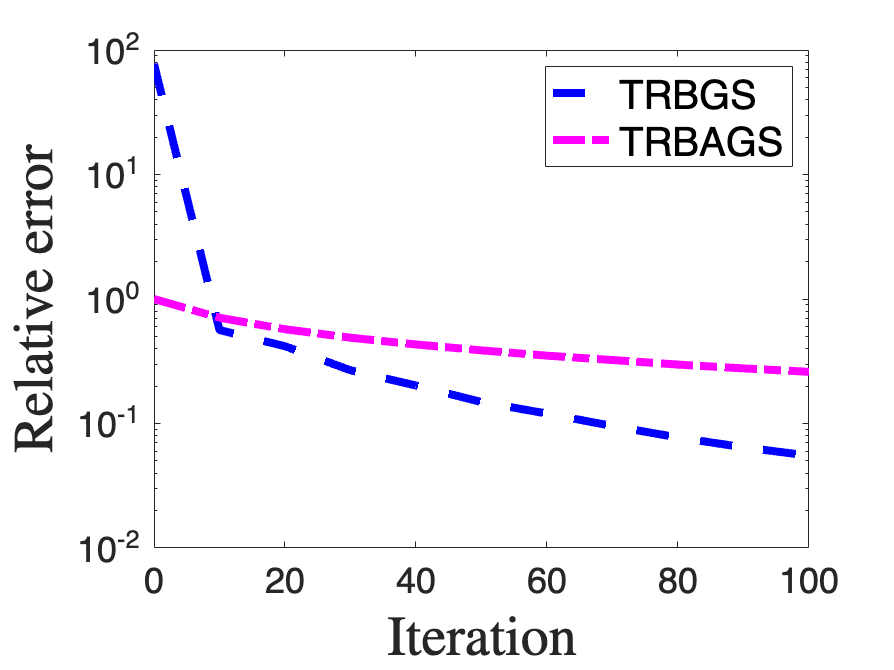

% Plot relative error vs iterations for tRBGS and tRBAGS
figure();
semilogy(0:sep:num_its,errs(1:sep:num_its+1),line_styles{1},0:sep:num_its,errs_invf(1:sep:num_its+1),line_styles{5},'LineWidth',4)
hold on
set(gca,'FontSize',18)
xlabel('Iteration','Interpreter','latex','FontSize',28) 
ylabel('Relative error','Interpreter','latex','FontSize',28) 
legend(legendStrings1,legendStrings2,'FontSize',20)
saveas(gca,fullfile(figsdest,'TRBGS_vs_TRBAGS_over_const_abs_err.png'))
hold off

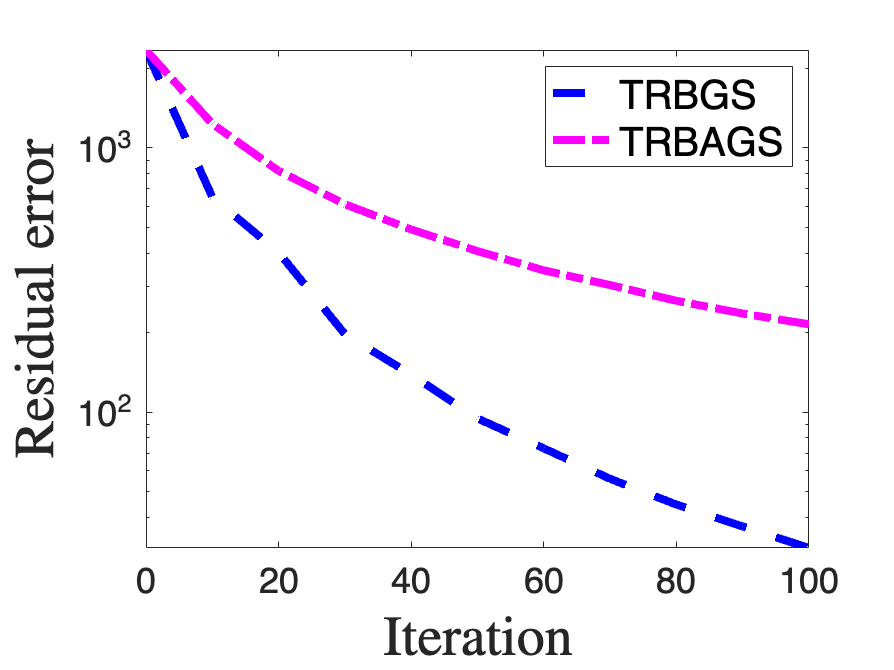

% Plot residual error vs iterations for tRBGS and tRBAGS
figure();
semilogy(0:sep:num_its,res_errs(1:sep:num_its+1),line_styles{1},0:sep:num_its,res_errs_invf(1:sep:num_its+1),line_styles{5},'LineWidth',4)
hold on
set(gca,'FontSize',18)
xlabel('Iteration','Interpreter','latex','FontSize',28) 
ylabel('Residual error','Interpreter','latex','FontSize',28) 
legend(legendStrings1,legendStrings2,'FontSize',20)
saveas(gca,fullfile(figsdest,'TRBGS_vs_TRBAGS_over_const_res_err.png'))
hold off

### **Case 2: Inconsistent, overdetermined tensor linear system**

First, we construct the tensors involved in the regression problem.

% Define tensor sizes
l = 10;
p = 30;
n = 20;
m = 30;

% Generate normally distributed pseudorandom tensors
A = randn(m,n,p);
X_true = randn(n,l,p);

% Generate component in col(A)^perp
Y_tild = randn(m,l,p);
X_tild = tprod(tpinv(A),Y_tild);
Y_perp = Y_tild - tprod(A,X_tild);

% Generate consistent and inconsistent measurements
B_true = tprod(A, X_true);
B = B_true + 0.005*Y_perp;

% Compute the least-norm solution 
X_ln = tprod(tpinv(A),B); 

Next, we implement tRBGS and tRBAGS for this system.

% Run some iterations of tRBGS and tRBAGS
[errs,res_errs] = TRBGS_err(A,B,zeros(n,l,p),num_its,X_true,X_ln,block_size);
[errs_invf,res_errs_invf] = TRBAGS_err(A,B,zeros(n,l,p),num_its,X_true,X_ln,block_size,weights);

Finally, we examine our results by plotting errors versus iterations.

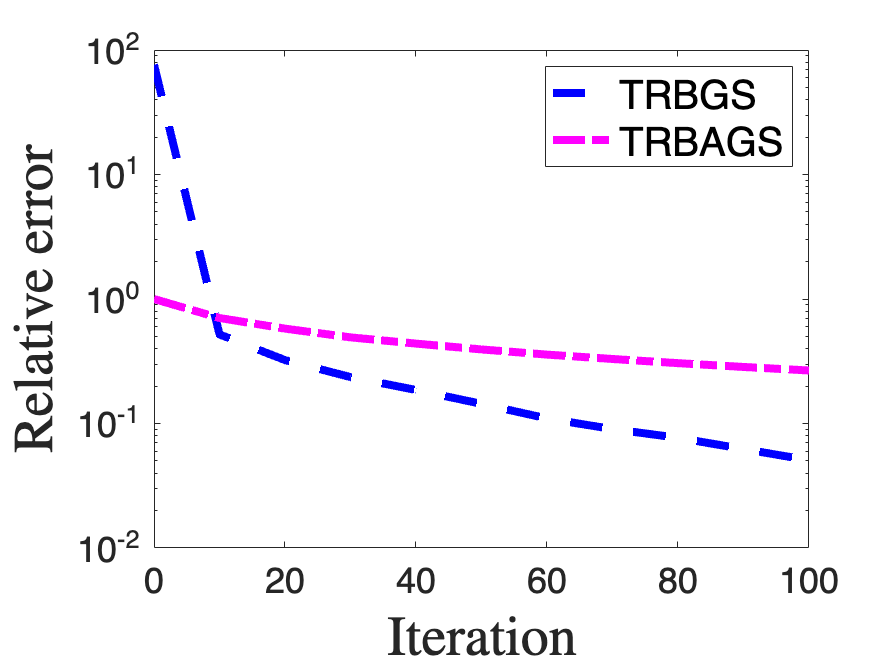

% Plot relative error vs iterations for tRBGS and tRBAGS
figure();
semilogy(0:sep:num_its,errs(1:sep:num_its+1),line_styles{1},0:sep:num_its,errs_invf(1:sep:num_its+1),line_styles{5},'LineWidth',4)
hold on
set(gca,'FontSize',18)
xlabel('Iteration','Interpreter','latex','FontSize',28) 
ylabel('Relative error','Interpreter','latex','FontSize',28) 
legend(legendStrings1,legendStrings2,'FontSize',20)
saveas(gca,fullfile(figsdest,'TRBGS_vs_TRBAGS_over_inconst_abs_err.png'))
hold off

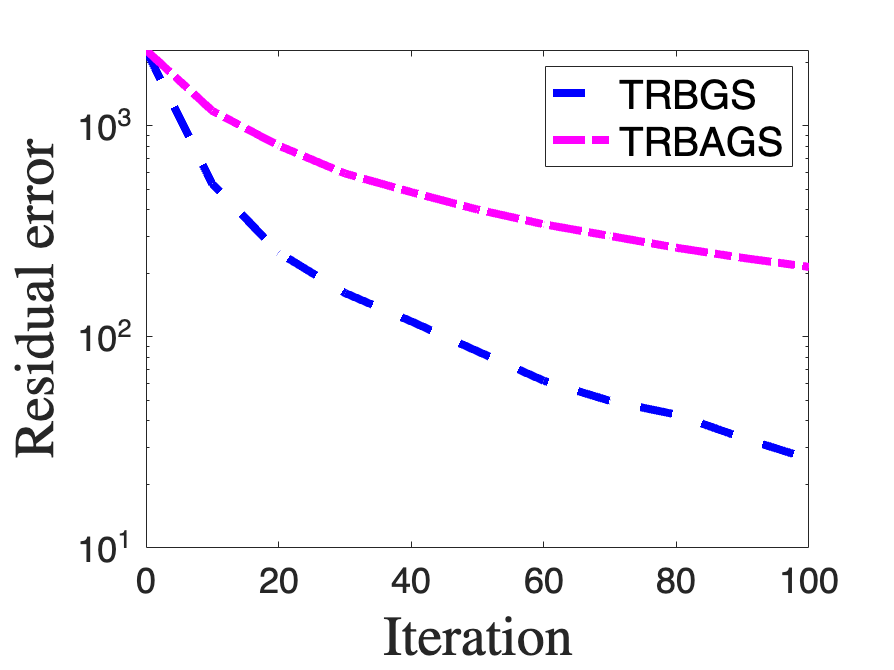

% Plot residual error vs iterations for tRBGS and tRBAGS
figure();
semilogy(0:sep:num_its,res_errs(1:sep:num_its+1),line_styles{1},0:sep:num_its,res_errs_invf(1:sep:num_its+1),line_styles{5},'LineWidth',4)
hold on
set(gca,'FontSize',18)
xlabel('Iteration','Interpreter','latex','FontSize',28) 
ylabel('Residual error','Interpreter','latex','FontSize',28) 
legend(legendStrings1,legendStrings2,'FontSize',20)
saveas(gca,fullfile(figsdest,'TRBGS_vs_TRBAGS_over_inconst_res_err.png'))
hold off

### **Case 3: Consistent, underdetermined tensor linear system**

First, we construct the tensors involved in the regression problem.

% Define tensor sizes
l = 20;
p = 10;
n = 30;
m = 10;

% Generate normally distributed pseudorandom tensors
A = randn(m,n,p);
X_true = randn(n,l,p);

% Generate consistent measurements
B = tprod(A,X_true);

% Compute the least-norm solution 
X_ln = tprod(tpinv(A),B); 

Next, we implement tRBGS and tRBAGS for this system.

% Run some iterations of tRBGS and tRBAGS
[errs,res_errs] = TRBGS_err(A,B,zeros(n,l,p),num_its,X_true,X_ln,block_size);
[errs_invf,res_errs_invf] = TRBAGS_err(A,B,zeros(n,l,p),num_its,X_true,X_ln,block_size,weights);

Finally, we examine our results by plotting errors versus iterations.

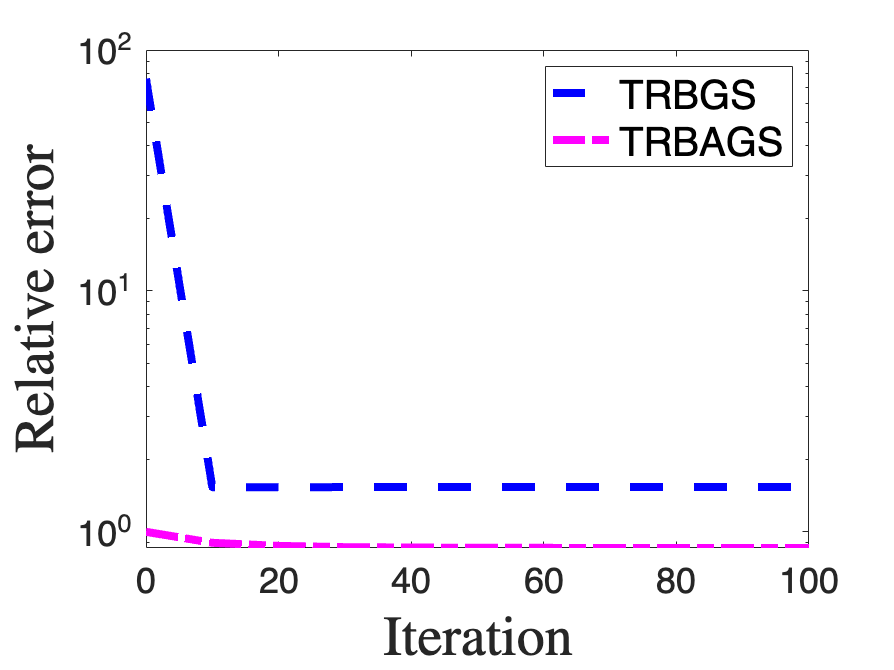

% Plot relative error vs iterations for tRBGS and tRBAGS
figure();
semilogy(0:sep:num_its,errs(1:sep:num_its+1),line_styles{1},0:sep:num_its,errs_invf(1:sep:num_its+1),line_styles{5},'LineWidth',4)
hold on
set(gca,'FontSize',18)
xlabel('Iteration','Interpreter','latex','FontSize',28) 
ylabel('Relative error','Interpreter','latex','FontSize',28) 
legend(legendStrings1,legendStrings2,'FontSize',20)
saveas(gca,fullfile(figsdest,'TRBGS_vs_TRBAGS_under_const_abs_err.png'))
hold off

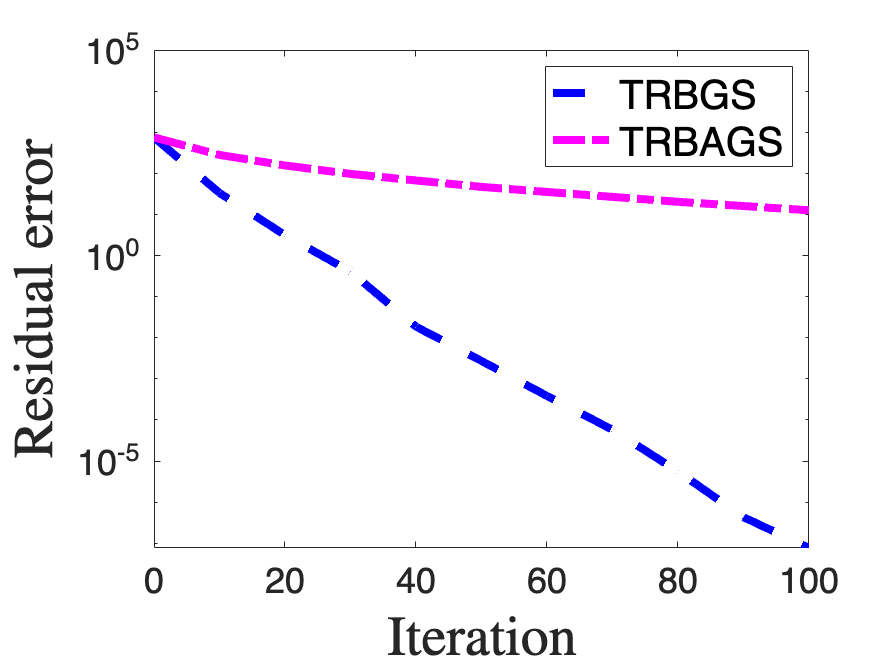

% Plot residual error vs iterations for tRBGS and tRBAGS
figure();
semilogy(0:sep:num_its,res_errs(1:sep:num_its+1),line_styles{1},0:sep:num_its,res_errs_invf(1:sep:num_its+1),line_styles{5},'LineWidth',4)
hold on
set(gca,'FontSize',18)
xlabel('Iteration','Interpreter','latex','FontSize',28) 
ylabel('Residual error','Interpreter','latex','FontSize',28) 
legend(legendStrings1,legendStrings2,'FontSize',20)
saveas(gca,fullfile(figsdest,'TRBGS_vs_TRBAGS_under_const_res_err.png'))
hold off